**Sample Study of Selected Simulations**

TheFiles = dir("cd\..\..\TSI_V5\SampleRuns\*.mat")

TheFiles = 3×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


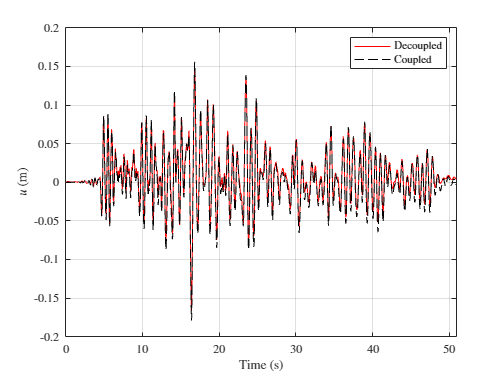

close all
% Load Coupled Analysis
load(strcat(TheFiles(1).folder, '/', TheFiles(1).name))
xddot_d = BridgeResponse.X(1, :);    % Accelerations of bridge


% Load Decoupled Analysis
load(strcat(TheFiles(3).folder, '/', TheFiles(3).name))


xddot_c = BridgeResponse.X(1, :);    % Accelerations of bridge


plot(tt, xddot_d, 'r-', ...
     tt, xddot_c, 'k--'), xlim([0, inf]), xlabel('Time (s)'), ylabel('$u$ (m)'), grid, legend('Decoupled', 'Coupled')

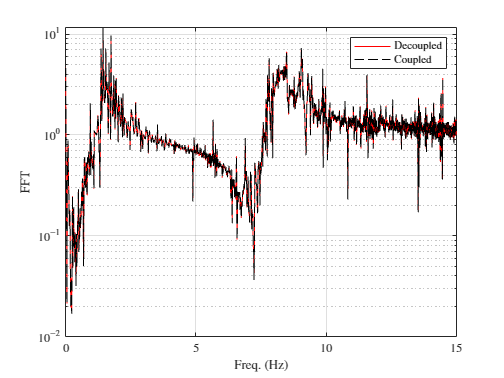

close all
[ff, Y1, Y1_all] = MyFFT(dtt, xddot_c);
[ff, Y, Y_all] = MyFFT(dtt, xddot_d);
[ff, U, U_all] = MyFFT(dtt, urec);

P = U .* (Y1./Y - 1);
P_all = U_all .* (Y1_all./Y_all - 1);

semilogy(ff, Y./(U), 'r', ...
       ff, Y1./(U + P) , 'k--'), xlim([0 15]), grid on, xlabel('Freq. (Hz)'), ylabel('FFT'), legend('Decoupled', 'Coupled')

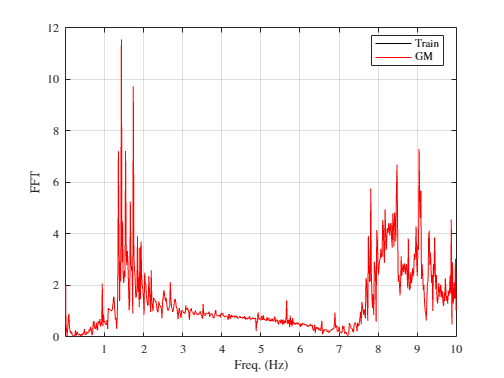


close all
TF1 = Y./U;
TF2 = Y1./(U + P);

plot(ff, TF1, 'k', ...
     ff, TF2, 'r'), xlim([0.01 10.0]), legend('Train', 'GM', Location='best'), grid on, xlabel('Freq. (Hz)'), ylabel('FFT')